% Specify the filename
filename = 'email-Enron.txt';

% Read the edge list, skipping the first 4 comment lines
edgeList = dlmread(filename, '\t', 4, 0);


% Convert to MATLAB 1-based indexing
edgeList = edgeList + 1;

% Assuming edgeList is already loaded and adjusted for 1-based indexing

numNodes = max(edgeList(:));
numEdges = size(edgeList, 1);

% Prepare the indices
rows = [edgeList(:,1); edgeList(:,2)];
cols = [1:numEdges, 1:numEdges]';
% Assign +1 to the first node and -1 to the second node of each edge
vals = [ones(numEdges, 1); -ones(numEdges, 1)];  % (2 * numEdges x 1)

% Build the incidence matrix using the 'sparse' function
B = sparse(rows, cols, vals, numNodes, numEdges);

% Assuming B is already defined and constructed

% Step 1: Compute the Laplacian matrix
L = B * B';

% Step 2: Extract the degree matrix D
D = spdiags(diag(L), 0, size(L,1), size(L,2));  % Efficiently create sparse diagonal matrix

% Step 3: Compute the adjacency matrix A
A = D - L;

% Step 4: Assert that the adjacency matrix is correctly formatted

% Find the non-zero elements of A
[i, j, v] = find(A);

% Identify diagonal elements
isDiagonal = (i == j);
vDiag = v(isDiagonal);

% Assert that the diagonal elements are zero (no self-loops)
assert(all(vDiag == 0), 'Adjacency matrix contains self-loops.');

% Identify off-diagonal elements
isOffDiagonal = ~isDiagonal;
vOffDiag = v(isOffDiagonal);

% Assert that all non-zero off-diagonal elements are greater than or equal to zero
assert(all(vOffDiag >= 0), 'Adjacency matrix has negative off-diagonal entries.');

% Assert that the adjacency matrix is symmetric
diffA = A - A';
[~, ~, vDiff] = find(diffA);
assert(isempty(vDiff), 'Adjacency matrix is not symmetric.');

% Proceed with analysis using A

% Compute the degree sequence
degree_seq = sum(A, 2);

% Display basic statistics
numNodes = size(A, 1);
numEdges = nnz(triu(A));  % Number of edges (counting upper triangle to avoid double counting)
average_degree = mean(degree_seq);

disp(['Number of nodes: ', num2str(numNodes)]);

Number of nodes: 36692


disp(['Number of edges: ', num2str(numEdges)]);

Number of edges: 183831


disp(['Average degree: ', num2str(average_degree)]);

Average degree: 20.0404


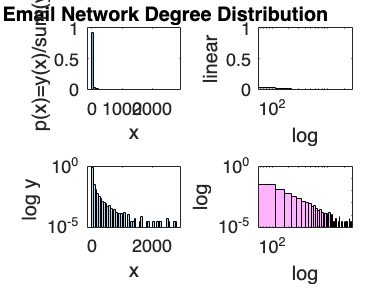


% Plot the degree distribution
nbins = 50;
figID = 1;
plot_distribution(degree_seq, 'Enron Email Network Degree Distribution', nbins, figID);